# Database Testing Framework

*Test MATLAB® code against databases running in Docker®*

## Introduction

The code in this project allows you to test *MATLAB* code that requires a database by using a local instance of the database server running in *Docker*.

The following databases are currently supported:

- *Microsoft SQL Server*® *2017* & *2019* (latest published)

- *PostgreSQL*® (latest published)

- *SQLite* (does not require *Docker*).

By creating tests that inherit from the relevant test class, the *Docker* container will automatically be spun up and a connection created. The test class also provides methods to create database checkpoints, restore the database to that checkpoint, delete the checkpoint, and import backup files (e.g. from your production database).

### Why use Docker

You might want to run the test database in *Docker* for a number of reasons:

- A permanent test server instance may not be available.

- You want complete control over the server instance, which your database administrator may not be willing to grant.

- To run tests in parallel without risk of interference.

- To run code against the database safe in the knowledge that it cannot do any permanent damage.

- To run code against a database that is starting from a completely clean slate.

## Getting started

### Ensure Database Toolbox™ installed

This code requires [*Database Toolbox*](https://www.mathworks.com/help/database/). Run this code to check if it is installed:

ver('database')

The output should look like:

### Install Docker

Download and install [*Docker Desktop*](https://www.docker.com/products/docker-desktop) (free). During installation, select the option for Linux containers and start the *Docker* server.

### Install database drivers

- *Microsoft SQL Server*: Most *Windows®* computers have *Microsoft SQL Server* drivers installed by default. If not, you can [download them yourself](https://www.microsoft.com/en-us/download/details.aspx?id=53339).

- *PostgreSQL*: you will need the [corresponding drivers](https://www.postgresql.org/ftp/odbc/versions/).

### Test installation

Run the following command:

result = runtests('dbtest.checkInstallation')

You will need to review and accept the EULA that is displayed for the relevant database product. The output should look like this:

The installation test will test that:

- The Database Testing Framework is correctly installed.

- That it is able to talk to *Docker*.

- That *Docker* is able to pull container images from the internet.

The test uses *Microsoft SQL Server 2019* as the test server. It does not test all possible database servers.

The first time that you run a test that requires a *Docker* database, *Docker* will download and install the corresponding image. The test setup process will take longer to run this first time.

## Types of testing

Testing can be performed in two different modes:

- Automated tests - write a [unit test class](https://www.mathworks.com/help/matlab/class-based-unit-tests.html) to run your tests automatically and report the result.

- Interactive testing - set up your *MATLAB* environment to communicate with the database server without writing tests in advance.

### Test superclasses

The following test superclasses are provided:

### **Automated testing**

To create an automated test, your test should inherit from the relevant `dbtest``.``With*` test class.

For example, for *Microsoft SQL Server 2019*:

The `dbtest.With*` superclasses provide the property `DatabaseConnection`. This is an ODBC [connection object](https://www.mathworks.com/help/database/ug/database.odbc.connection.html) as per the [*Database Toolbox*](https://www.mathworks.com/help/database/). You can use this object to execute database commands just as you would with the *Database Toolbox*. For example:

### **Interactive testing**

To test a database interactively, start by creating a testcase using the `forInteractiveUseWithAutoSetup` method of the relevant `dbtest.With*` class. For example:

tc = dbtest.WithMsSqlServer2019.forInteractiveUseWithAutoSetup()

The variable `tc` contains the `DatabaseConnection` property as before.

When `tc` goes out of scope (explicit deletion, or it gets cleared), the database server instance will be torn down.

clear tc


ans = 

  1×0 empty string array



*Note: if other variables exist which also maintain a connection the database server, the *Docker* container may not be torn down correctly.*

## Checkpoints

The testing framework has an important utility that allows you to create and restore the database to certain states that you define. We call these *checkpoints*. 

Set up an interactive session for the following examples to work:

tc = dbtest.WithMsSqlServer2019.forInteractiveUseWithAutoSetup();

### View existing checkpoints

To find the name of user-defined database checkpoints you can access the property `CheckpointNames`. By default, no checkpoints are defined.

tc.CheckpointNames

### Creating a new checkpoint

Before modifying the database, let's create a checkpoint:

tc.createCheckpoint("EmptyDatabase")

Now create a table:

tbl = table("Batman", 35,"Male", 200,"Gotham",'VariableNames',{'LastName' 'Age' 'Gender' 'Height' 'Location'});

ans = 1×5 table
     LastName     Age     Gender     Height     Location 
    __________    ___    ________    ______    __________

    {'Batman'}    35     {'Male'}     200      {'Gotham'}


tc.DatabaseConnection.sqlwrite("Characters",tbl);
tc.DatabaseConnection.sqlread("Characters")

ans = 1×1 cell array
    {'Characters'}


We can see that the table now appears in the list:

tc.TableNames

Now create another checkpoint:

tc.createCheckpoint("DataAdded")

ans = 1×2 string array
    "DataAdded"    "EmptyDatabase"


Review the checkpoint names:

tc.CheckpointNames

### Restoring to a checkpoint

Let's revert the state of the database back to when it was empty:

tc.restoreCheckpoint("EmptyDatabase")


ans =

  0×1 empty cell array



The tables list is now empty:

tc.TableNames

### Close all database connections before restoring to a checkpoint

To restore a checkpoint, the working database is first deleted, and then restored from the checkpoint. To delete the working database, **there cannot be any open connections to it**. 

If you use `tc.DatabaseConnection`, this disconnect-reconnect process is handled automatically for you. If you maintain your own connections, you will have to do this process yourself.

As good practice, checkpoints are generally only ever restored at the very beginning of a test method, or better still, as part of a test method setup method. If you're changing database checkpoints mid test, you're probably not writing good tests! 

If you're maintaining a reference to the database via your own test class property, you're in danger of writing leaky tests and should avoid it.

### Deleting a checkpoint

If required, a checkpoint can be deleted:

tc.deleteCheckpoint("DataAdded")
tc.CheckpointNames

ans = "EmptyDatabase"

### Importing from a backup file

You may have existing data that you wish to populate your test environment with. For example, a recent backup of your production system so that you can debug an issue reported by an end user.

**Warning**: `importBackupFile` drops the existing database before performing the import. If you wish to save the current state of the database, create a checkpoint first.

The file format of the backup file is specific to the database that you are using. Database management tools such as *Microsoft SQL Server Management Studio*® will generate them automatically. Please consult the documentation for your database management tool for more details.

Now end the session:

clear tc

## Test setup configuration

Before running tests, you will probably want to pre-populate the database with data and checkpoints. This can be done at three different levels: test, class, or fixture.

### Test level

This can be done using a method with a `TestMethodSetup` attribute. In the following example, the database is restored to the `TestStart` checkpoint before every test contained within this class. We assume that you have created the `TestStart` checkpoint already.

*Note: If a the database is set to be a shared fixture, any database changes will be visible to **all** test classes that are run **after* `tMyTest`*. However, you cannot guarantee what order that will be. If you want to ensure that data is available for all test classes, set up data at the fixture level (below).*

### Class level

This can be done using a method with a `TestClassSetup` attribute. In the following example, a checkpoint `TestStart` is created. `createInitialCheckpoint` is run once per class.

*Note: If a the database is set to be a shared fixture, any database changes will be visible to **all** test classes that are run **after* `tMyTest`*. However, you cannot guarantee what order that will be. If you want to ensure that data is available for all test classes, set up data at the fixture level (below).*

# Advanced topics

The following topics require detailed technical knowledge and should only be investigated once you are comfortable with the standard features of the Database Testing Framework discussed above.

## Test setup confirguration at the fixture level

A shared fixture allows you to reuse the same database server instance across multiple test classes. 

A common task is to initialise that database server instance with data and checkpoints that can be used by all test classes. This is achieved in two parts:

- Write a setup function.

- Write a custom test class that references the setup function.

### Setup function

Your setup function should accept one input argument `tc` which is the interface to the database.

`tc` has the property

and four methods:

An example setup function is shown below which loads a backup file and creates two checkpoints:

Your setup function must be on the *MATLAB* path for use by your custom test class.

### Custom test class

The syntax for creating a custom test class is a little complex. Start by copying the code below.

This class needs to identify the database server needed at three different locations. In this example we're using `PostgreLatest`. Change it to match the server that you want to use.

- Within the class attributes:

- Inside the `getDbSharedFixture` method:

- Inside the function `forInteractiveUseWithAutoSetup`:

Secondly, change `@setupFcn` to match the name of your own setup function.

Now that your custom test class is complete, you can then create tests by inheriting from `MyCustomizedPostgreSql`:

## Prebuilt fixtures

During development, you may work iteratively on tests and run them frequently. If using the database fixture, each time you run a test, the *Docker* container is spun up and then shut down. This can add up to be a lot of time. Instead, it can be useful to create the fixture once manually, and then give it to the test to use each time. This is known as a [prebuilt fixture](https://www.mathworks.com/help/matlab/ref/matlab.unittest.testrunner-class.html).

Note that when using a prebuilt fixture, the state of the database does not get reset from one test to another.

### Example test classes

Image that we have 2 test classes that share a common fixture (via `dbtest.WithMsSqlServer2019`).

### Run tests automatically

Create a test suite from the two classes, a test runner, and finally run the tests:

Example output:

### Create fixture manually

Now we create the fixture manually. All fixtures have a method called `setup`. We must manually call this to setup the fixture.

Which produce the output:

Once we have done this, we can tell the test runner that it can use this fixture rather than creating its own.

This produces the following output:

Note that the `MsSqlServer2019` fixture is neither setup nor torn down when running the tests as the existing instance is being used.

## Port Randomisation

When a *Docker* database server instance is created, a free random port will be allocated. This is to allow multiple server instances to be created simultaneously without clashes. 

If you need to know the port number (e.g. to connect to the server with a database management program), you can obtain it from *Docker* directly. In *MATLAB*, enter the command

Example output is

Under the column `Ports` we see that the default port of 1433 has been mapped to 55233. So 55233 is what you need to enter into your program that connects to the server.

# Legal

## Licence

The code in this Toolbox is governed by the licence contained in the `license.txt` file.

type license.txt


Copyright (c) 2020, The MathWorks, Inc.
All rights reserved.
Redistribution and use in source and binary forms, with or without modification, are permitted provided that the following conditions are met:
1. Redistributions of source code must retain the above copyright notice, this list of conditions and the following disclaimer.
2. Redistributions in binary form must reproduce the above copyright notice, this list of conditions and the following disclaimer in the documentation and/or other materials provided with the distribution.
3. In all cases, the software is, and all modifications and derivatives of the software shall be, licensed to you solely for use in conjunction with MathWorks products and service offerings. 
THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRI

## Database server EULAs

The database server products that run in *Docker* may have end user licence agreements (EULAs) associated with them. The code in this Toolbox will not ask *Docker* to run a container until you have acknowledged the EULA.

By default, the website showing the relevant EULA or link will be displayed and you will be asked if you accept it. If you decline, the code will stop running and exit.

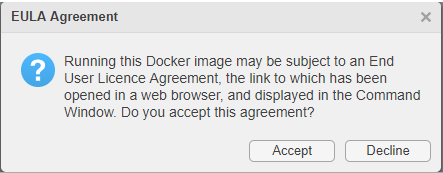

## Trademarks

*MATLAB* and *Simulink* are registered trademarks of The MathWorks, Inc. See [www.mathworks.com/trademarks](http://www.mathworks.com/trademarks) for a list of additional trademarks. Other product or brand names may be trademarks or registered trademarks of their respective holders.

*Docker* and the Docker logo are trademarks or registered trademarks of Docker, Inc. in the United States and/or other countries. Docker, Inc. and other parties may also have trademark rights in other terms used herein. 

*SQL Server* and *SQL Server Management Studio* is a registered trademark of Microsoft Corporation. *Windows* is a registered trademark of Microsoft Corporation in the United States and other countries. 

*MySQL* is a registered trademark of MySQL AB.